# Cvičení 1 - Bonus - B2M31AEDA

## 1) Fibonacciho posloupnost

Fibonacciho posloupnost vypadá následovně:


$$\begin{array}{l}
F=0,1,1,2,3,5,\ldots\;\\
F_0 =0,F_1 =1,F_n =F_{n-1} +F_{n-2} \;,\ldots
\end{array}$$


Napište funkci, která bude brát jediný, libovolný, nezáporný, celočíselný vstup `N`, a bude generovat na výstupu příslušnou `N`-tou hodnotu Fibonacciho posloupnosti.

% Vaše funkce pro výpočet N-tého prvku Fibonacciho posloupnosti
function Fn = calculateNthFibonacciNumber(n)
    phi = (1 + sqrt(5)) / 2;
    phi_dash = (1 - sqrt(5)) / 2;

    Fn = (phi^n - phi_dash^n) / sqrt(5);
end

Vydělením dvou sousedících prvků Fibonacciho posloupnosti pro N >> 1 (např. 1000), vám vyjde přibližná hodnota Zlatého řezu 𝜑.


$$\hat{\textrm{𝜑}} =\frac{F_N }{F_{N-1} };N>1$$


Čím větší bude `N`, tím bude hodnota blíže skutečné hodnotě 𝜑. Ilustrujte pomocí grafu, jak se výpočet zlatého řezu pomocí Fibonacciho čísel blíží jeho skutečné hodnotě. Vyneste do grafu hodnoty aproximací pro tolik `N`, kolik uznáte za vhodné (dokud se hodnota dostatečně nepřiblíží) a konstantní čáru reprezentující skutečnou hodnotu. Nezapomeňte popsat osy, aktivovat mřížku, dodat legendu atd.

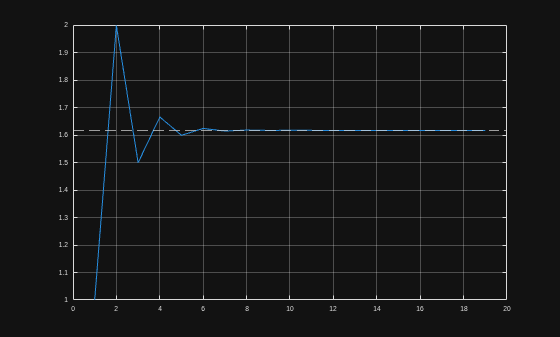

N = 20;
Ns = 1:N;
Fns = arrayfun(@calculateNthFibonacciNumber, Ns);

phis = Fns(2:end) ./ Fns(1:end-1);
phiTrue = (1 + sqrt(5)) / 2;

figure;
plot(Ns(1:end-1), phis);
hold on;
yline(phiTrue, '--');
hold off;
grid on;

#### Otázky:

- Slovy napište minimálně 3 případy, kde se Fibonacciho posloupnost vyskytuje v přírodě.

- 1/ Pocty semen dvou sousednich spiral ve stredu slunecnice jsou typicky shodne s dvema po sobe jdoucimi Finonacciho cisly.

- 2/ Listy na stonku rostlin maji casto od sebe uhel rovny zlatemu rezu.

- 3/ Velikosti papiru formatu A (napr. A0, A1, ...) tvori primo Fibonacciho posloupnost co se tyka jejich obsahu.

## 2) Pascalova matice

Napište funkci, která bude generovat Pascalovu matici. Funkce bude mít jeden celočíselný, kladný vstup `N`, a na výstupu bude generovat matici `P` o velikosti `N×N`, která bude symetrická a bude obsahovat hodnoty binomiálních koeficientů (více info v návodu ke cvičení).

Matice bude iniciovaná jako matice jedniček, a dále se budou hodnoty matice vypočítávat tak, aby každý prvek byl dán součtem prvků které jsou o jeden řádek výše a jeden sloupec vlevo:


$$P\left(i,j\right)=P\left(i-1,j\right)+P\left(i,j-1\right)\;;1\le i,j\le N$$


function pascalMatrix = calculatePascalMatrix(n)
    pascalMatrix = ones(n);

    for k = 2:n
        for l = 2:n
            pascalMatrix(k, l) = pascalMatrix(k - 1, l) + pascalMatrix(k, l - 1);
        end
    end

ans =            1           1           1           1           1           1           1           1           1           1
           1           2           3           4           5           6           7           8           9          10
           1           3           6          10          15          21          28          36          45          55
           1           4          10          20          35          56          84         120         165         220
           1           5          15          35          70         126         210         330         495         715
           1           6          21          56         126         252         462         792        1287        2002
           1           7          28          84         210         462         924        1716        3003        5005
           1           8          36         120         330         792        1716        3432        6435       11440
           1           9  

end

calculatePascalMatrix(10)

#### Otázky:

- Slovy odpovězte, jakým způsobem byste mohli z Pascalovy matice získat čísla Fibonacciho posloupnosti.

- Oznacme n-te Fibonacciho cislo F_n a cislo na pozici (i, j) v Pascalove matici P_{ij}, potom F_{n + 1} dostaneme tak, ze secteme vsechny P_{ij}, pro nez plati i + 2j - 3 = n. Tedy ku prikladu pro n = 4 secteme P_{51} + P_{32} + P_{13} = 1 + 3 + 1 = 5 = F_5

## 3) Mandelbrotova množina

Pomocí návodu si naprogramujte výpočet Mandelbrotovy množiny a zobrazte si jí. Postup naleznete v návodu ke cvičení.

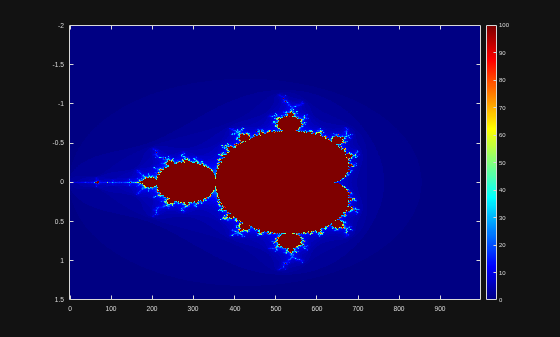

function renderMaldelbrotSet(n, iterCount)
    mandelbrotMatrix = zeros(n);
    xMatrix = ones(n, 1) * linspace(-2, 1.5, n);
    yMatrix = xMatrix.';

    initialStep = xMatrix + 1i .* yMatrix;
    step = initialStep;

    for k = 1:iterCount
        step = step .* step + initialStep;
        mandelbrotMatrix = mandelbrotMatrix + (abs(step) <= 2);
    end

    imagesc(xMatrix(:, 1), yMatrix(:, 1), mandelbrotMatrix)
end


renderMaldelbrotSet(1000, 100);
colorbar
colormap jet